% DD2423 Lab1, part 2 & 3

## 2.3 Filtering procedure - Display convolutions

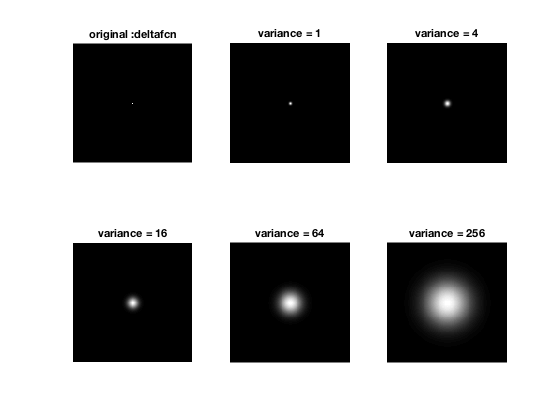

variance = 1


ans =     1.0000    0.0000
    0.0000    1.0000


variance = 4


ans =     4.0000    0.0000
    0.0000    4.0000


variance = 16


ans =    16.0000    0.0000
    0.0000   16.0000


variance = 64


ans =    64.0000    0.0000
    0.0000   64.0000


variance = 256


ans =   255.7247   -0.0000
   -0.0000  255.7247


clc
clear

%variance_t = [0.1, 0.3, 1.0, 10.0, 100.0]; %test correspond to Q14 & Q15
variance_t = [1.0, 4.0, 16.0, 64.0, 256.0]; %test correspond to Q16

s_t = length(variance_t);

figure(23)
subplot(2 , 3 , 1);
showgrey(deltafcn(128, 128));
title('original :deltafcn');
j = 2;
for t = variance_t
    disp(['variance = ', num2str(t)]);
    psf = gaussfft(deltafcn(128, 128), t);
    %psf = discgaussfft(deltafcn(128, 128), t); % Method of the first one.
    %What's the difference???
    subplot(2 , 3, j);
    j  = j + 1;
    variance(psf)
    showgrey(psf)
    title(['variance = ', num2str(t)]);
end


%saveas(gcf,'./Figures/Lab1_2-1_Q14_fig.png','png')

## 2.3 Filtering procedure - Compare discrete kernel, convolution and discgaussfft

ans =    128   128


ans =    128   128


ans =    128   128


ans =    128   128


ans =    128   128


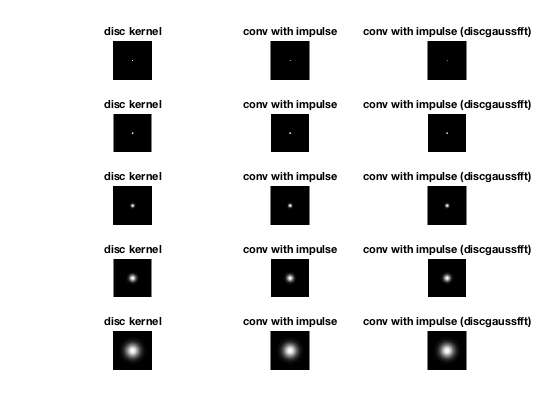

clc
clear

%variance_t = [0.1, 0.3, 1.0, 10.0, 100.0]; %test correspond to Q14 & Q15
variance_t = [1.0, 4.0, 16.0, 64.0, 256.0]; %test correspond to Q16

s_t = length(variance_t);

figure(23)
%subplot(2 , 3 , 1);
%showgrey(deltafcn(128, 128));
%title('original :deltafcn');
%j = 2;
for i = 1:size(variance_t,2)
    % Plot discrete kernel
    subplot(5, 3, (i-1)*3+1);
    [x y] = meshgrid(-128/2 : 128/2-1, -128/2 : 128/2-1);
    gaussf = (1 / (2 * pi * variance_t(i))) * exp (- (x .* x + y .* y) ./ (2 * variance_t(i)));
    showgrey(gaussf)
    title('disc kernel')
    
    subplot(5, 3, (i-1)*3+2);
    psf = gaussfft(deltafcn(128, 128), variance_t(i));
    showgrey(psf)
    title('conv with impulse')
    
    subplot(5, 3, (i-1)*3+3);
    psf2 = discgaussfft(deltafcn(128, 128), variance_t(i));
    showgrey(psf2)
    title('conv with impulse (discgaussfft)')
end


%saveas(gcf,'./Figures/Lab1_2-1_Q14_figcomp.png','png')

## 2.3. Plot gaussian kernels

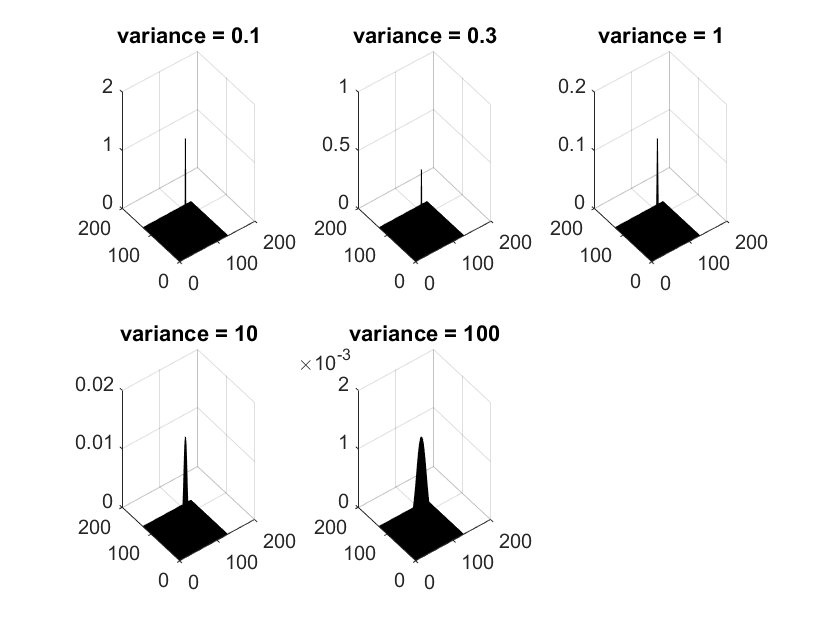

clc
clear

variance_t = [0.1, 0.3, 1.0, 10.0, 100.0]; %test correspond to Q14 & Q15
%variance_t = [1.0, 4.0, 16.0, 64.0, 256.0]; %test correspond to Q16
figure(230)
i = 1;
for t = variance_t
    subplot(2 , 3 , i);
    i = i +1;
    xsize = 128;
    ysize = 128;
    [x y] = meshgrid(-xsize/2 : xsize/2-1, -ysize/2 : ysize/2-1);
    gaussf = (1 / (2 * pi * t)) * exp (- (x .* x + y .* y) ./ (2 * t));
    surf(gaussf);
    colormap;
    title(['variance = ', num2str(t)]);
end

%saveas(gcf,'./Figures/Lab1_2-1_Q15_fig.png','png')

## 2.3 Blur images with Gaussian filter

variance = 1


ans =    1.0e+03 *

    1.4035   -0.0317
   -0.0317    1.5010


variance = 4


ans =    1.0e+03 *

    1.4031   -0.0336
   -0.0336    1.5003


variance = 16


ans =    1.0e+03 *

    1.4011   -0.0370
   -0.0370    1.4973


variance = 64


ans =    1.0e+03 *

    1.3939   -0.0398
   -0.0398    1.4857


variance = 256


ans =    1.0e+03 *

    1.3782   -0.0288
   -0.0288    1.4526


variance = 1


ans =    1.0e+03 *

    1.3986    0.0209
    0.0209    1.5709


variance = 4


ans =    1.0e+03 *

    1.4006    0.0190
    0.0190    1.5702


variance = 16


ans =    1.0e+03 *

    1.4037    0.0149
    0.0149    1.5674


variance = 64


ans =    1.0e+03 *

    1.4063    0.0073
    0.0073    1.5561


variance = 256


ans =    1.0e+03 *

    1.4019    0.0010
    0.0010    1.5155


variance = 1


ans =   965.5607   68.8532
   68.8532  546.5052


variance = 4


ans =   970.0728   64.3254
   64.3254  553.3584


variance = 16


ans =   981.4643   53.9145
   53.9145  615.6963


variance = 64


ans =    1.0e+03 *

    1.0130    0.0198
    0.0198    0.8547


variance = 256


ans =    1.0e+03 *

    1.0987   -0.0120
   -0.0120    1.2492


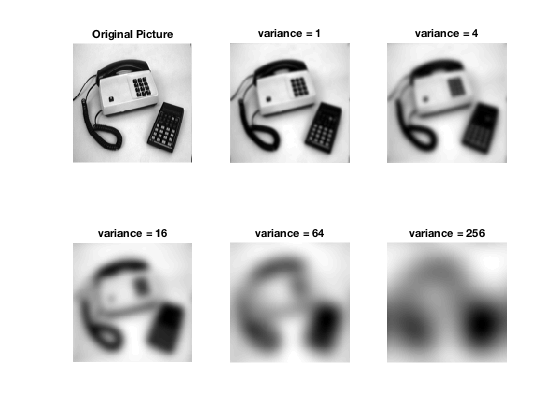

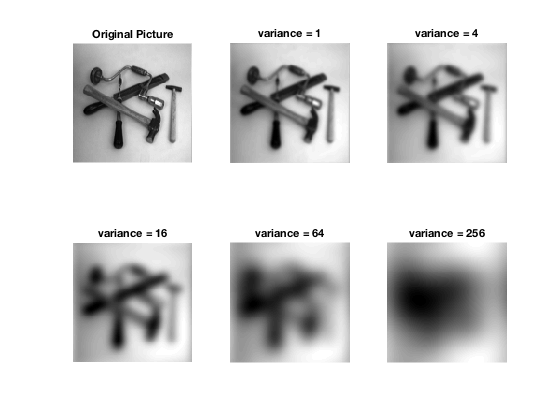

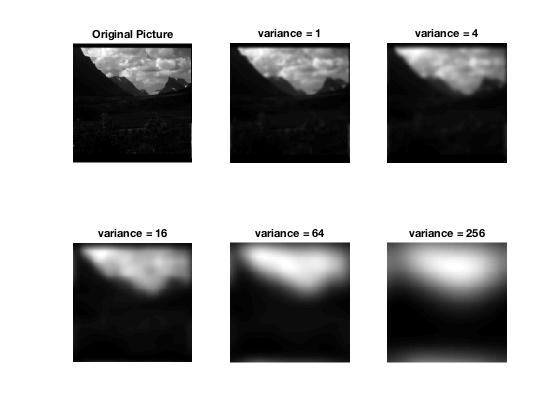

clc
clear
img = cat(3, phonecalc128, few128, nallo128);
variance_t = [1.0, 4.0, 16.0, 64.0, 256.0];

for i = 1:size(img,3) 
figure(23+i)
F = img(:,:,i);
subplot(2, 3, 1);
showgrey(F);
title('Original Picture'); 
j = 2;
for t = variance_t
    disp(['variance = ', num2str(t)]);
    psf = gaussfft(F, t);
    %psf = discgaussfft(F, t); % Method of the first one.
    subplot(2 , 3, j);
    j  = j + 1;
    variance(psf)
    showgrey(psf)
    title(['variance = ', num2str(t)]);
end
end